clear all;
close all;

n = 48;
k = 1000;
eta = 1.96; %normal distribution percentage point at (1+gamma)/2 with gamma=0.95
ub = [];
lb = [];
true_mean = 0.5;
c = 0;

for i=1:k
    x = rand(n,1);
    sample_mean = mean(x);
    sample_std = std(x);
    bound = eta*sample_std/sqrt(n);
    ub(end+1) = sample_mean + bound;
    lb(end+1) = sample_mean - bound;
    if true_mean < lb(end) || true_mean > ub(end)
        c = c + 1;
    end
end

c*100/k

ans = 6.2000

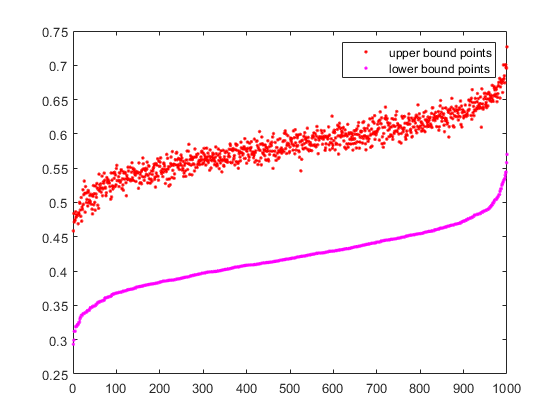


[lb_ordered,idx] = sort(lb,'ascend');
ub_ordered = ub(idx);
plot(ub_ordered,'.r');
hold on
plot(lb_ordered,'.m');
hold off
legend('upper bound points','lower bound points');


eta = 2.012; %student's distribution percentage point at (1+gamma)/2 with gamma=0.95 for n = 47
clear lb_ordered ub_ordered idx
lb = [];
ub = [];
true_mean = 0;
c = 0;

for i=1:k
    x = randn(n,1);
    sample_mean = mean(x);
    sample_std = std(x);
    bound = eta*sample_std/sqrt(n);
    ub(end+1) = sample_mean + bound;
    lb(end+1) = sample_mean - bound;
    if true_mean < lb(end) || true_mean > ub(end)
        c = c + 1;
    end
end

c*100/k

ans = 5

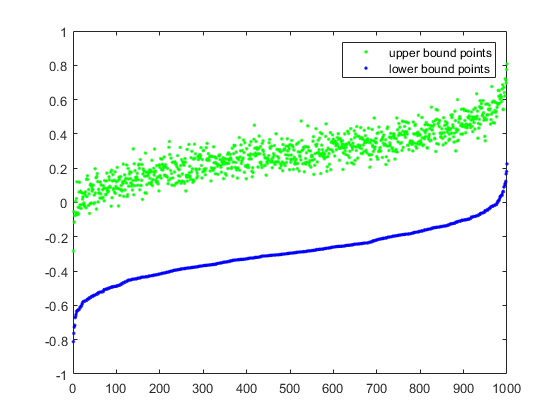


[lb_ordered,idx] = sort(lb,'ascend');
ub_ordered = ub(idx);
plot(ub_ordered,'.g');
hold on
plot(lb_ordered,'.b');
hold off
legend('upper bound points','lower bound points');